clc
clear
Kt = 0.011;
Km = 327*10^-6;
m = 1.513;
Ixx = 0.0185;
Iyy = 0.0201;
Izz = 0.0286;
g = 9.82;
lroll = 0.175;
lpitch = 0.175;

A = [zeros(6,6)  [0 0 0 0 -g 0; 0 0 0 g 0 0 ; zeros(4,6)];
    eye(6) zeros(6,6)];
B = [zeros(4,2) [Kt/m -(lroll*Kt)/(Ixx) -(lpitch*Kt)/(Iyy) (Km)/(Izz); 
    Kt/m (lroll*Kt)/(Ixx) (lpitch*Kt)/(Iyy) (Km)/(Izz); 
    Kt/m (lroll*Kt)/(Ixx) -(lpitch*Kt)/(Iyy) -(Km)/(Izz); 
    Kt/m -(lroll*Kt)/(Ixx) (lpitch*Kt)/(Iyy) -(Km)/(Izz)] zeros(4,6)].';

C = [0 0 0 1 0 0 0 0 0 0 0 0 ;
     0 0 0 0 1 0 0 0 0 0 0 0 ;
     0 0 0 0 0 1 0 0 0 0 0 0 ;
     0 0 0 0 0 0 1 0 0 0 0 0 ;
     0 0 0 0 0 0 0 1 0 0 0 0 ;
     0 0 0 0 0 0 0 0 1 0 0 0 ;
     0 0 0 0 0 0 0 0 0 1 0 0 ;
     0 0 0 0 0 0 0 0 0 0 1 0 ;
     0 0 0 0 0 0 0 0 0 0 0 1 ;];
D = zeros(6,4);

s=tf('s')

s =
 
  s
 
Continuous-time transfer function.
Model Properties


tfs = (C/(s*eye(12)-A))*B;

omega_roll_u = tfs(1,2)

omega_roll_u =
 
  0.1041
  ------
    s
 
Continuous-time transfer function.
Model Properties


omega_pitch_u = tfs(2,2)

omega_pitch_u =
 
  0.09577
  -------
     s
 
Continuous-time transfer function.
Model Properties


omega_yaw_u = tfs(3,1)

omega_yaw_u =
 
  0.01143
  -------
     s
 
Continuous-time transfer function.
Model Properties



theta_omega_roll = tfs(7,2)/omega_roll_u

theta_omega_roll =
 
                0.1041 s
  ------------------------------------
  0.1041 s^2 - 4.141e-18 s + 1.541e-18
 
Continuous-time transfer function.
Model Properties


phi_omega_pitch = tfs(8,2)/omega_pitch_u

phi_omega_pitch =
 
               0.09577 s
  ------------------------------------
  0.09577 s^2 + 7.64e-18 s + 3.054e-19
 
Continuous-time transfer function.
Model Properties


psi_omega_yaw = tfs(9,2)/omega_yaw_u

psi_omega_yaw =
 
                0.01143 s
  -------------------------------------
  0.01143 s^2 + 1.503e-18 s + 4.922e-35
 
Continuous-time transfer function.
Model Properties



x_phi = tfs(4,1)/tfs(8,2)

x_phi =
 
                  0.9405 s^2 + 7.502e-17 s + 2.999e-18
  ---------------------------------------------------------------------
  0.09577 s^4 - 1.738e-17 s^3 - 5.018e-17 s^2 - 2.552e-18 s + 1.038e-18
 
Continuous-time transfer function.
Model Properties


y_theta = tfs(5,2)/tfs(7,2)

y_theta =
 
                 1.022 s^2 - 4.066e-17 s + 1.514e-17
  -----------------------------------------------------------------
  0.1041 s^4 - 8.04e-18 s^3 - 2.306e-17 s^2 - 3.72e-18 s - 1.76e-18
 
Continuous-time transfer function.
Model Properties



Kp = 1;
Ki = .1;
Kd = 0;
N = 20;
D = Kp + Ki/s + Kd * s*N/(s+N)

D =
 
  s + 0.1
  -------
     s
 
Continuous-time transfer function.
Model Properties


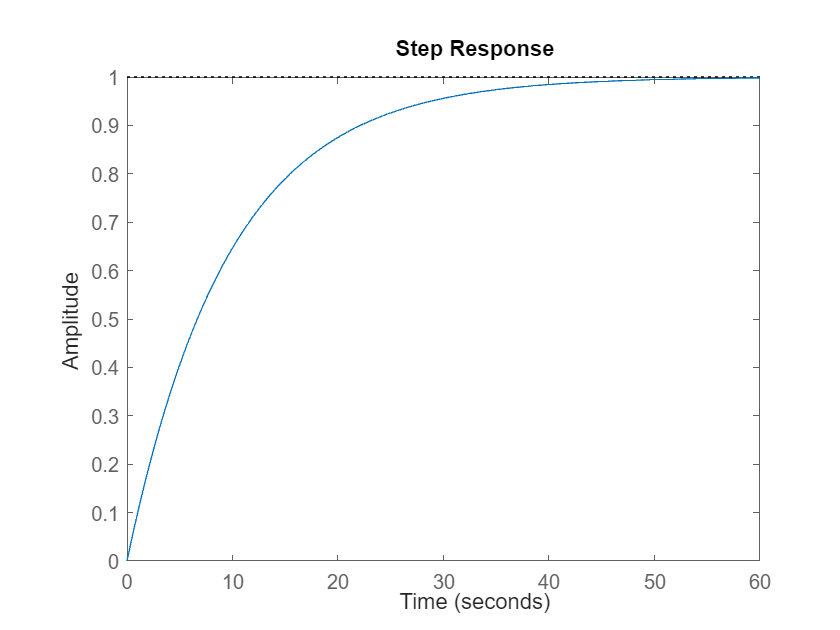



step(feedback(omega_roll_u,1))


pole(feedback(x_phi,1))

ans =    0.0000 + 3.1337i
   0.0000 - 3.1337i
  -0.0000 + 0.0000i
  -0.0000 - 0.0000i


zero(feedback(x_phi,1))

ans = 1.0e-08 *

  -0.0000 + 0.1786i
  -0.0000 - 0.1786i


pole(feedback(y_theta,1))

ans =    0.0000 + 3.1337i
   0.0000 - 3.1337i
   0.0000 + 0.0000i
   0.0000 - 0.0000i


zero(feedback(y_theta,1))

ans = 1.0e-08 *

   0.0000 + 0.3849i
   0.0000 - 0.3849i


pole(feedback(tfs(3,1),1))

ans = -0.0114

pole(feedback(tfs(4,2),1))

ans =   -0.9848 + 0.0000i
   0.0000 + 0.9848i
   0.0000 - 0.9848i
   0.9848 + 0.0000i


pole(feedback(tfs(5,2),1))

ans =   -0.7109 + 0.7109i
  -0.7109 - 0.7109i
   0.7109 + 0.7109i
   0.7109 - 0.7109i


pole(feedback(tfs(6,1),1))

ans =   -0.0000 + 0.0853i
  -0.0000 - 0.0853i
